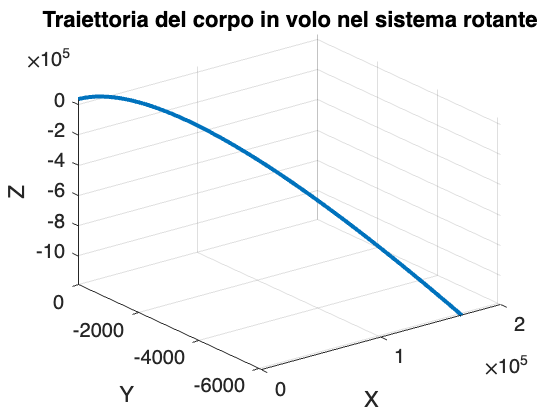

% Parametri del corpo in volo
m = 1;  % massa del glider kg
g = 9.81;  % accelerazione dovuta alla gravità in m/s^2

% Parametri del sistema rotante (Terra)
Omega = 7.2921e-5;  % velocità angolare della Terra in rad/s

% Funzione del sistema di equazioni differenziali
ode = @(t, y) [
    y(4);  % dx/dt = vx
    y(5);  % dy/dt = vy
    y(6);  % dz/dt = vz
    2 * Omega * y(5) + Omega^2 * y(1);  % d(vx)/dt = F_Coriolis_x + F_centrifuga_x
    -2 * Omega * y(4) + Omega^2 * y(2);  % d(vy)/dt = F_Coriolis_y + F_centrifuga_y
    -g + Omega^2 * y(3)  % d(vz)/dt = F_Coriolis_z + F_centrifuga_z - g
];

% Condizioni iniziali (posizione e velocità iniziali)
y0 = [0; 0; 35000 ; 335; 0; 0];  

% Intervallo temporale
tspan = [0 500];

% Risoluzione dell'equazione differenziale
options = odeset('RelTol', 1e-6, 'AbsTol', 1e-6);
[t, y] = ode45(ode, tspan, y0, options);

% Plot della traiettoria del corpo in volo
figure;
plot3(y(:, 1), y(:, 2), y(:, 3), 'LineWidth', 2);
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Traiettoria del corpo in volo nel sistema rotante');
grid on; 